% adding cross section to 3D scatter
% plotting only one dot per cell, the average pole age of the cell
%myfolder = '/MATLAB Drive/myfolder' ;   % new folder name 
%folder = mkdir([filepath,filesep,myfolder]) ;
%filepath  = [filepath,filesep,myfolder];
global i_cells cells x1 x2 y1 y2 z1 z2 lengths c1 c2 c x y z plot_range;
plot_range = [-100 100 -100 100 0 35];
i_cells =118;
file_path = sprintf('Cells/%d.txt',i_cells);
cells=importdata(file_path);

%x = [cells(:,4);cells(:,7)];
%y = [cells(:,5);cells(:,8)];
%z = [cells(:,6);cells(:,9)];
%c = [cells(:,27);cells(:,28)] %pole ages
x1 = cells(:,4);
x2 = cells(:,7);
y1 = cells(:,5);
y2 = cells(:,8);
z1 = cells(:,6);
z2 = cells(:,9);
lengths = cells(:,10);
c1 = cells(:,27); % p age
c2 = cells(:,28); % q age

c = (c1 + c2)/2; % average pole age for cells
% average co-ordinates
x = (x1 + x2)/2;
y = (y1 + y2)/2;
z = (z1 + z2)/2;

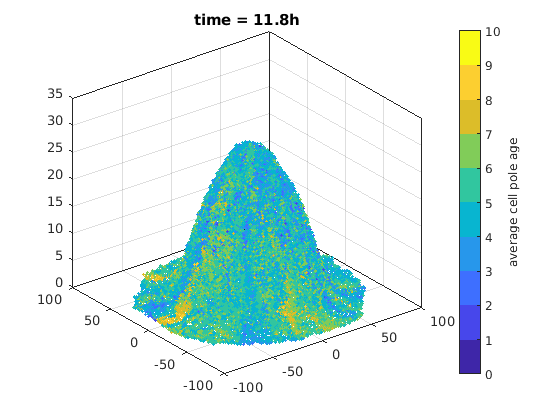


subplot(1,1,1)
scatter3(x,y,z,5,c, 'filled');
axis(plot_range)
box on
h1=colorbar;
colormap(parula(10))
caxis([0, 10]);
title(['time = ' num2str(i_cells*.1) 'h'])

h1.Label.String = 'average cell pole age';

global thickness dot_size;
dot_size =6;
thickness =30;

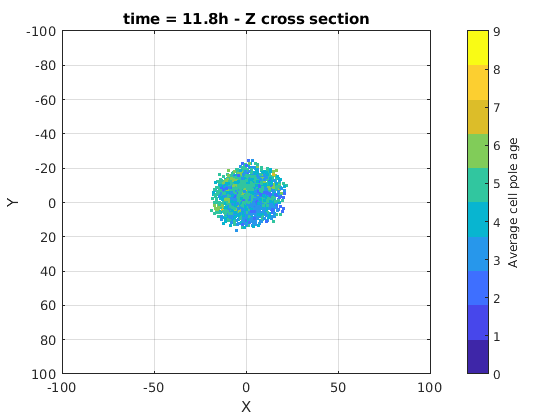

z_cut =25;
cross_section(z_cut,'Z', "Average cell pole age")

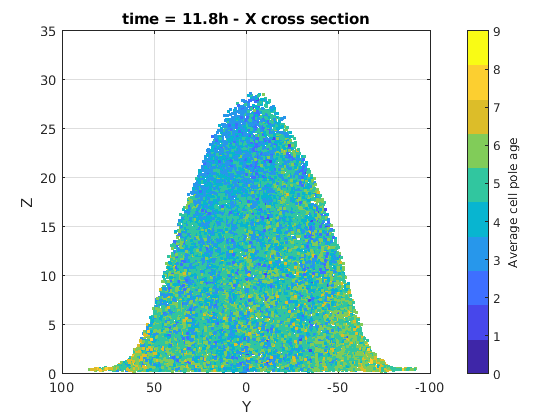

x_cut =4;
cross_section(x_cut,'X', "Average cell pole age")

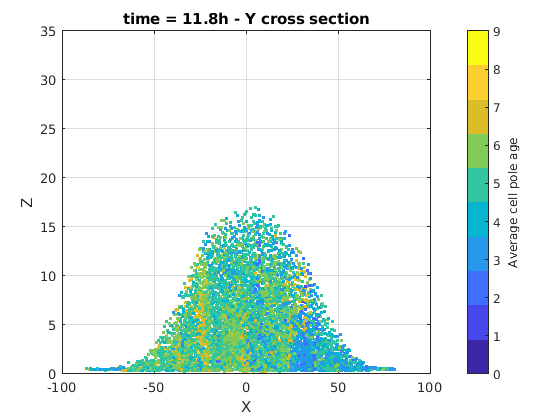

y_cut =33;
cross_section(y_cut,'Y', "Average cell pole age")

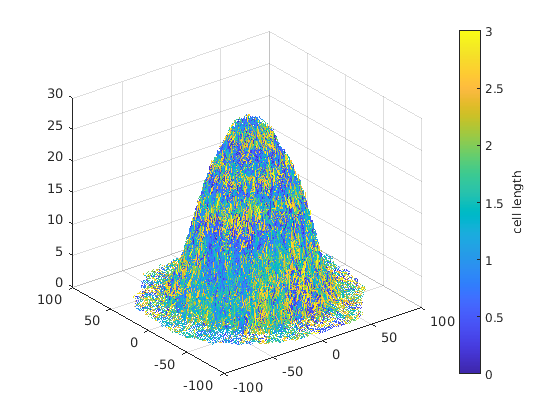

length_plot(x1,y1,z1,x2,y2,z2,lengths)